# 1: Modeling the Spread of a Virus

Working with live script makes it easier to analyze the problem while changing parameters.

## Values Needed To Apply Numeric Solutions

Step size: 

h = 1/500;

Interval in days:

tmin = 0;
tmax = 100;
t = tmin:h:tmax;
m = (tmax-tmin)/h                     % number of iterations

m = 50000

## Parameters That Effect The Spread of The Virus

c = 4; % encounters per day
B = 0.2; % transmission probability per encounter
a = 0.125; % rate at which infected become infectious (per day)
g = 0.1; % rate at which an infected person becomes symptomatic (per day)
w = 0.2; % recovery rate
AB = 1000; % HOSPITAL BEDS



## Simplified Mathematical Model of The Problem

5 Sub Groups of Population:

S = zeros(1,m); % Susceptibles
E = zeros(1,m); % Exposed
I = zeros(1,m); % Infected
M = zeros(1,m); % Medically Symptomatic
R = zeros(1,m); % Recovered

Initial Conditions:

S(1) = 10000;
E(1) = 10;
I(1) = 0;
M(1) = 0;
R(1) = 0;

Differential Equations:

dS = @(S,E,I,M,R) -c*B*(I./(S+E+I+M+R)).*S; % S prime
dE = @(S,E,I,M,R) c*B*(I./(S+E+I+M+R)).*S - a*E; % E prime
dI = @(S,E,I,M,R) a*E - g*I; % I prime
dM = @(S,E,I,M,R) g*I - w*M; % M prime
dR = @(S,E,I,M,R) w*M; % R prime

## More Compact Form of The Model

Creating a function handle for first order differential equations and a vector matrix to store values of populations; makes our code neater and more readable.

% function handle
dy{1} = @(V) dS(V(1),V(2),V(3),V(4),V(5));
dy{2} = @(V) dE(V(1),V(2),V(3),V(4),V(5));
dy{3} = @(V) dI(V(1),V(2),V(3),V(4),V(5));
dy{4} = @(V) dM(V(1),V(2),V(3),V(4),V(5));
dy{5} = @(V) dR(V(1),V(2),V(3),V(4),V(5));

% vector matrix
V = [S; E; I; M; R];

## Euler Solution

Even though the Euler method is a very simple and direct method; it is first order convergent, so its accuracy is poor compared to other methods.

Apply the Euler method:

tic
for i=1:m
    for j=1:5
        V(j,i+1) = V(j,i) + h*dy{j}(V(:,i));
    end
end
elapsedTime_e = toc % calculate the elapsed time

elapsedTime_e = 0.4718

Store the values found in this solution:

S_e = V(1,:); 
E_e = V(2,:);
I_e = V(3,:);
M_e = V(4,:);
R_e = V(5,:);
V_e = [S_e; E_e; I_e; M_e; R_e];

Necessary code to plot the results:

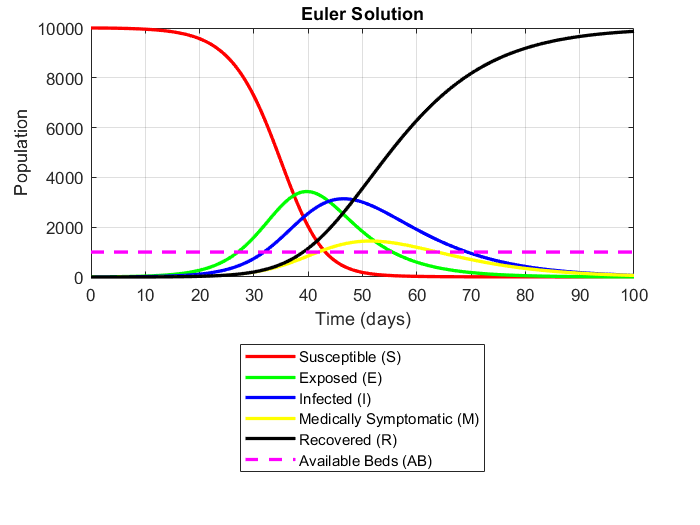

figure
plot(t,S_e, 'r', 'linewidth', 2)
hold on, grid on
plot(t,E_e, 'g', 'linewidth', 2)
plot(t,I_e, 'b', 'linewidth', 2)
plot(t,M_e, 'y', 'linewidth', 2)
plot(t,R_e, 'k', 'linewidth', 2)
plot([tmin, tmax],[AB, AB], '--m', 'linewidth', 2)
title('Euler Solution')
xlabel('Time (days)')
ylabel('Population')
h2=legend('Susceptible (S)', 'Exposed (E)', 'Infected (I)',...
    'Medically Symptomatic (M)', 'Recovered (R)',...
    'Available Beds (AB)');
set(h2, 'Location', 'southoutside')

## 4th Order Runge Kutta Solution

Runge Kutta method that we used is fourth order convergent which is far more accurate than Euler method but it is less accurate than ode45 function which is fifth order convergent.

First, create the function handle to find f values (f1, f2, f3, f4) and the vector matrix to store these f values:

f{1} = @(g,V,h,fv) g(V);
f{2} = @(g,V,h,fv) g(V + h/2*fv(:,1));
f{3} = @(g,V,h,fv) g(V + h/2*fv(:,2));
f{4} = @(g,V,h,fv) g(V + h*fv(:,3));
fv = zeros(5,4); % Each row stores f values for each equation

Apply the RK4 method:

tic
for i=1:m
    for j=1:4 % four f values
        for k=1:5 % five equations
            fv(k,j)= f{j}(dy{k}, V(:,i), h, fv); 
        end
    end
    V(:,i+1) = V(:,i) + h/6*(fv(:,1) + 2*fv(:,2) + 2*fv(:,3) + fv(:,4));
end
elapsedTime_rk4 = toc % calculate the elapsed time

elapsedTime_rk4 = 2.9763

Store the values found in this solution:

S_rk = V(1,:); 
E_rk = V(2,:);
I_rk = V(3,:);
M_rk = V(4,:);
R_rk = V(5,:);
V_rk = [S_rk; E_rk; I_rk; M_rk; R_rk];

Necessary code to plot the results:

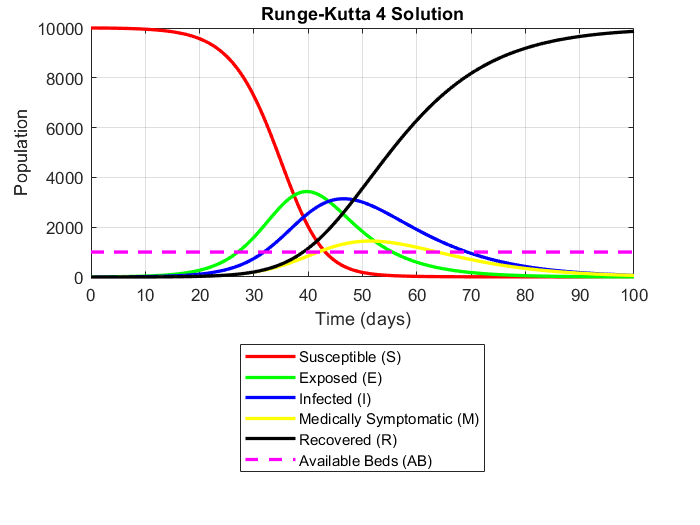

figure
plot(t,S_rk, 'r', 'linewidth', 2)
hold on, grid on
plot(t,E_rk, 'g', 'linewidth', 2)
plot(t,I_rk, 'b', 'linewidth', 2)
plot(t,M_rk, 'y', 'linewidth', 2)
plot(t,R_rk, 'k', 'linewidth', 2)
plot([tmin, tmax],[AB, AB], '--m', 'linewidth', 2)
title('Runge-Kutta 4 Solution')
xlabel('Time (days)')
ylabel('Population')
h1=legend('Susceptible (S)', 'Exposed (E)', 'Infected (I)',...
    'Medically Symptomatic (M)', 'Recovered (R)',...
    'Available Beds (AB)');
set(h1, 'Location', 'southoutside')

## ODE45 Solution

Ode45 is a very good solver for nonstiff equations that is fifth order convergent. It also adjusts the step size automatically to the requested accuracy which makes it an efficient solver at the same time. 

*(Note that for stiff equations ode45 spend a lot of computational work. It is better to choose other methods like ode23s which can solve stiff equations with very few steps.)*

I will create the figure now to run the code separetely and create before-after graphs side by side.

figure('Position',[10,10,1300,450])
f_Position=1;
f_name="before";

Ode45 takes three parameters in our use; these are odefcn function, tspan and y0. 

tspan is a one by two matrix which stores the minimum and maximum values of the interval:

tspan = [tmin tmax];

y0 is the initial values:

y0 = [10000, 10, 0, 0, 0];

Apply the ode45 function:

tic
[t_ode,y] = ode45(@(t,y) odefcn(y,c,B,a,g,w), tspan, y0);
elapsedTime_ode = toc % calculate the elapsed time

elapsedTime_ode = 0.1925

How many steps used in this solution:.

Steps_ode = length(t_ode)

Steps_ode = 125

Store the values found in this solution (in row vectors):

S_ode = y(:,1)';
E_ode = y(:,2)';
I_ode = y(:,3)';
M_ode = y(:,4)';
R_ode = y(:,5)';
V_ode = [S_ode; E_ode; I_ode; M_ode; R_ode];

Necessary code to plot the results:

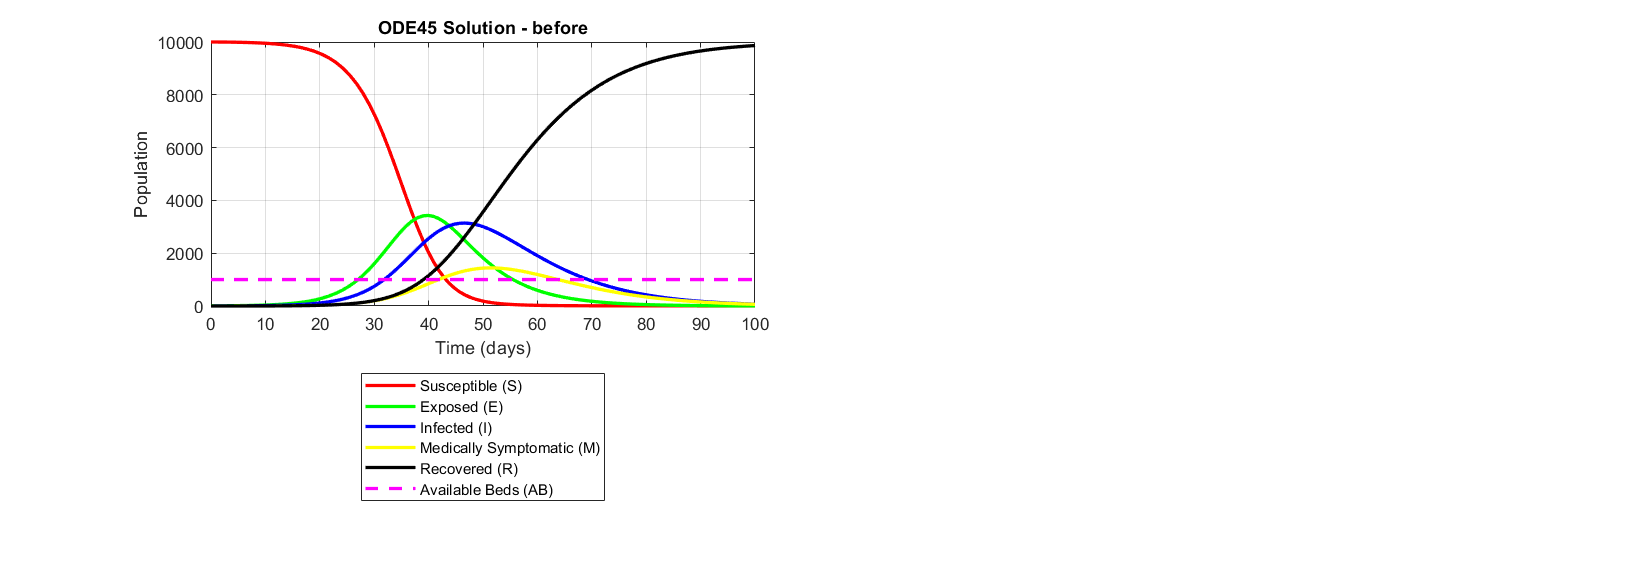

if(f_Position==3)
    f_Position=1;
    f_name="before";
elseif(f_Position==2)
    f_name="after";
end
titleName = "ODE45 Solution - "+f_name;
subplot(1,2,f_Position)
plot(t_ode,y(:,1),'r',t_ode,y(:,2),'g',t_ode,y(:,3),'b',t_ode,y(:,4),'y',...
    t_ode,y(:,5),'k',[tmin tmax],[AB AB],'--m','linewidth',2)
grid on
title(titleName)
xlabel('Time (days)')
ylabel('Population')
h3=legend('Susceptible (S)', 'Exposed (E)', 'Infected (I)',...
    'Medically Symptomatic (M)', 'Recovered (R)',...
    'Available Beds (AB)');
set(h3, 'Location', 'southoutside')

f_Position=f_Position+1;

odecfn is a local function which stores the first order differential equations:

function dydt = odefcn(y,c,B,a,g,w)
dydt = zeros(5,1);
dydt(1) = -c*B*(y(3)./(y(1)+y(2)+y(3)+y(4)+y(5))).*y(1);
dydt(2) = c*B*(y(3)./(y(1)+y(2)+y(3)+y(4)+y(5))).*y(1) - a*y(2);
dydt(3) = a*y(2) - g*y(3);
dydt(4) = g*y(3) - w*y(4);
dydt(5) = w*y(4);
end